# 034IN "Fundamentals of Automatic Control" - Introduction to MATLAB

# Part 4L-2 - Applications of the Laplace Transform

## Introduction

In this live script, we illustrate how to use the **Matlab Symbolic Toolbox** to determine the Laplace transform of a causal function of the independent variable time and the inveerse laplace transform corresponding to a given rational, stricly proper or simply proper, function of the complex variable $s$.

The importance of managing the Laplace transform will soon become clear (refer to **Part 2** of the class material)! 

Please refer also to the [LAPLACE_TRANSFORM](https://units.sharepoint.com/:b:/r/sites/PATC_CD2024_IN03_034IN_395497/Class%20Materials/MATLAB_LIVE-SCRIPTS/LAPLACE/FUNDAMENTALS_AUTOMATIC_CONTROL_2024-2025_LAPLACE_TRANSFORM.pdf?csf=1&web=1&e=lGZaTD) document in the MS Teams course file repository.

What you will learn: 

- How to solve an Ordinary Differential Equation (ODE) or an Integro-Differential Equation exploiting the Laplace transform.

- How to apply the Laplace transform in solving exercises of the 034IN course.

## Solution of a Linear ODE

### Introduction

Symbolic workflows keep calculations in their natural symbolic form rather than numerical form. This approach helps to understand the solution's properties and uses exact symbolic values. Numbers are substituted for symbolic variables only when a numerical result is required or cannot be continued in a symbolic manner.  

In general, the steps to solve an Ordinary Differential Equation (ODE) using the Laplace transform and the Symbolic Toolbox are as follows:

- Declare the variables and the equations.

- Solve the equations using the Laplace transform.

- Substitute numerical values.

- Plot the results.

- Analyse the results.

## Solution of a Second-Order Linear Differential Equation

We want to solve the ODE equation:


$$\frac{d^2\, y(t)}{d\,t^2} + 3 \frac{d\, y(t)}{d\,t} +2 y(t) = \left[1+3t\right]\cdot 1(t)$$


with initial conditions


$$y(0) = 1 \quad ,\qquad \left.\frac{d\,y}{dt} \right\vert_{t=0} =0$$


#### Step 0: Declare the Variables

clear variables

syms t y(t) u(t) Y s % the variables in the time and frequency domain
assume(t >=0)

u(t) = (1+3*t); % Note: You DO NOT NEED to write the Heaviside function explicitly!

y0VAL = 1;    % the initial conditions: the value y(0)
doty0VAL = 0; % the initial conditions: the first derivative at time instant 0

#### Step 1: Declare the ODE 

Firstly, declare the symbolic derivatives $\dot y$ and $\ddot y$ of the function $y(t)$

dot_y = diff(y,t);
ddot_y = diff(dot_y,t);

Then, declare the ODE equation. **Pay attention to the == symbol**

eqnODE = ddot_y + 3*dot_y + 2*y == u;

What does the equation look like?

disp(eqnODE)

#### Step 2 & 3: Solve the ODE Using the Laplace Transform & Substitute Numerical Values

Let's compute the Laplace transform of the ODE:

eqnLT = laplace(eqnODE, t, s);

What does the equation in the Laplace transform domain look like?

disp(eqnLT)

**Note**: In order to continue and solve the algebraic equation with the Laplace transform, we must replace all terms indicating Laplace transforms of the function $y(t)$ and its derivatives with symbolic variables.

eqnLT1 = subs(eqnLT,laplace(y,t,s),Y)
eqnLT2 = subs(eqnLT1, y(0), y0VAL)
eqnLT3 = subs(eqnLT2, subs(diff(y(t), t), t, 0), doty0VAL)

Finally, **solve the ODE**

Ysol = solve(eqnLT3, Y)
Ysol = simplify(expand(Ysol))

Let's **apply the inverse Laplace transform**:

ysol = ilaplace(Ysol)

That's it!

#### Step 4 & 5: Plot the results.

figure('Units','normalized','Position',[0.1,0.1,0.9,0.9])

$$\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=3\,t+1$$


fplot(ysol,[0 15], 'LineWidth', 3)                      
title('ODE solution')
ylabel('y(t)')
xlabel('t')
grid on
ylim([-1, max(ylim)])

$$3\,s\,\mathrm{laplace}\left(y\left(t\right),t,s\right)-3\,y\left(0\right)-s\,y\left(0\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+s^{2}\,\mathrm{laplace}\left(y\left(t\right),t,s\right)+2\,\mathrm{laplace}\left(y\left(t\right),t,s\right)=\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}$$

## The State Movement of a Continuous-time LTI System

Consider


$$\left\{ 
\begin{array}{lcl}
\dot{x} &=& \left[ \begin{array}{cc}
0 & 1 \\ 0  &-a
\end{array} \right] \, x + \left[ \begin{array}{c}
0 \\ K
\end{array} \right]\, u\\ \\
y &=& \left[ \begin{array}{cc} 1 & 0 \end{array} \right] \, x
\end{array}
\right.$$


and compute the state movement, starting from the initial state


$$x(0) = \left[ \begin{array}{c} 1\\0 \end{array} \right]$$


with the input


$$u(t) = 2 \sin \left(4 t+\frac{\pi}{3}\right) \cdot 1(t)$$


The state movement is expressed by  


$$x(t) = \displaystyle e^{At}\cdot x(0) + \displaystyle \int_{0}^{t} e^{A(t-\tau)} \cdot B u(\tau)\,d \, \tau $$


Let's compute the state movement, using the Symbolic Math Toolbox

syms s    % the Laplace transform variiable

$$eqnLT1 = 2\,Y-3\,y\left(0\right)+3\,Y\,s-s\,y\left(0\right)-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+Y\,s^{2}=\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}$$

syms a K  % the symbolic parameters into the state equations

$$eqnLT2 = 2\,Y-s+3\,Y\,s-\left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)+Y\,s^{2}-3=\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}$$

syms t    % the time as symbolic variable

$$eqnLT3 = 2\,Y-s+3\,Y\,s+Y\,s^{2}-3=\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}$$


% assigning the state equation matrices
A = [0 , 1; 0 -a]

$$Ysol = \frac{s+\frac{3\,\left(\frac{s}{3}+1\right)}{s^{2}}+3}{s^{2}+3\,s+2}$$

$$Ysol = \frac{s^{3}+3\,s^{2}+s+3}{s^{2}\,\left(s^{2}+3\,s+2\right)}$$

x0 = [1; 0]; % the initial state

B = [0; K]

$$ysol = \frac{3\,t}{2}+4\,{\mathrm{e}}^{-t}-\frac{5\,{\mathrm{e}}^{-2\,t}}{4}-\frac{7}{4}$$

C = [1 0];
D = 0;

Now define the symbolic matrix $(s I -A)$, used in the Laplace transform of the exponential matrix


$$\displaystyle \mathcal{L}\big\{ e^{At}\big\} = \displaystyle \left(sI-A\right)^{-1}$$


% now define the symbolic matrix (sI-A)
sIA = s*eye(size(A))-A;
sIA_inv = inv(sIA)

Now, let's compute the movement using the Laplace transform

Us = laplace(2*sin(4*t+pi/3))  % the Laplace transform of the input

Xs = sIA_inv*x0 + sIA_inv*B*Us % the Laplace transform of the state movement

Finally, by using the inverse Laplace transform

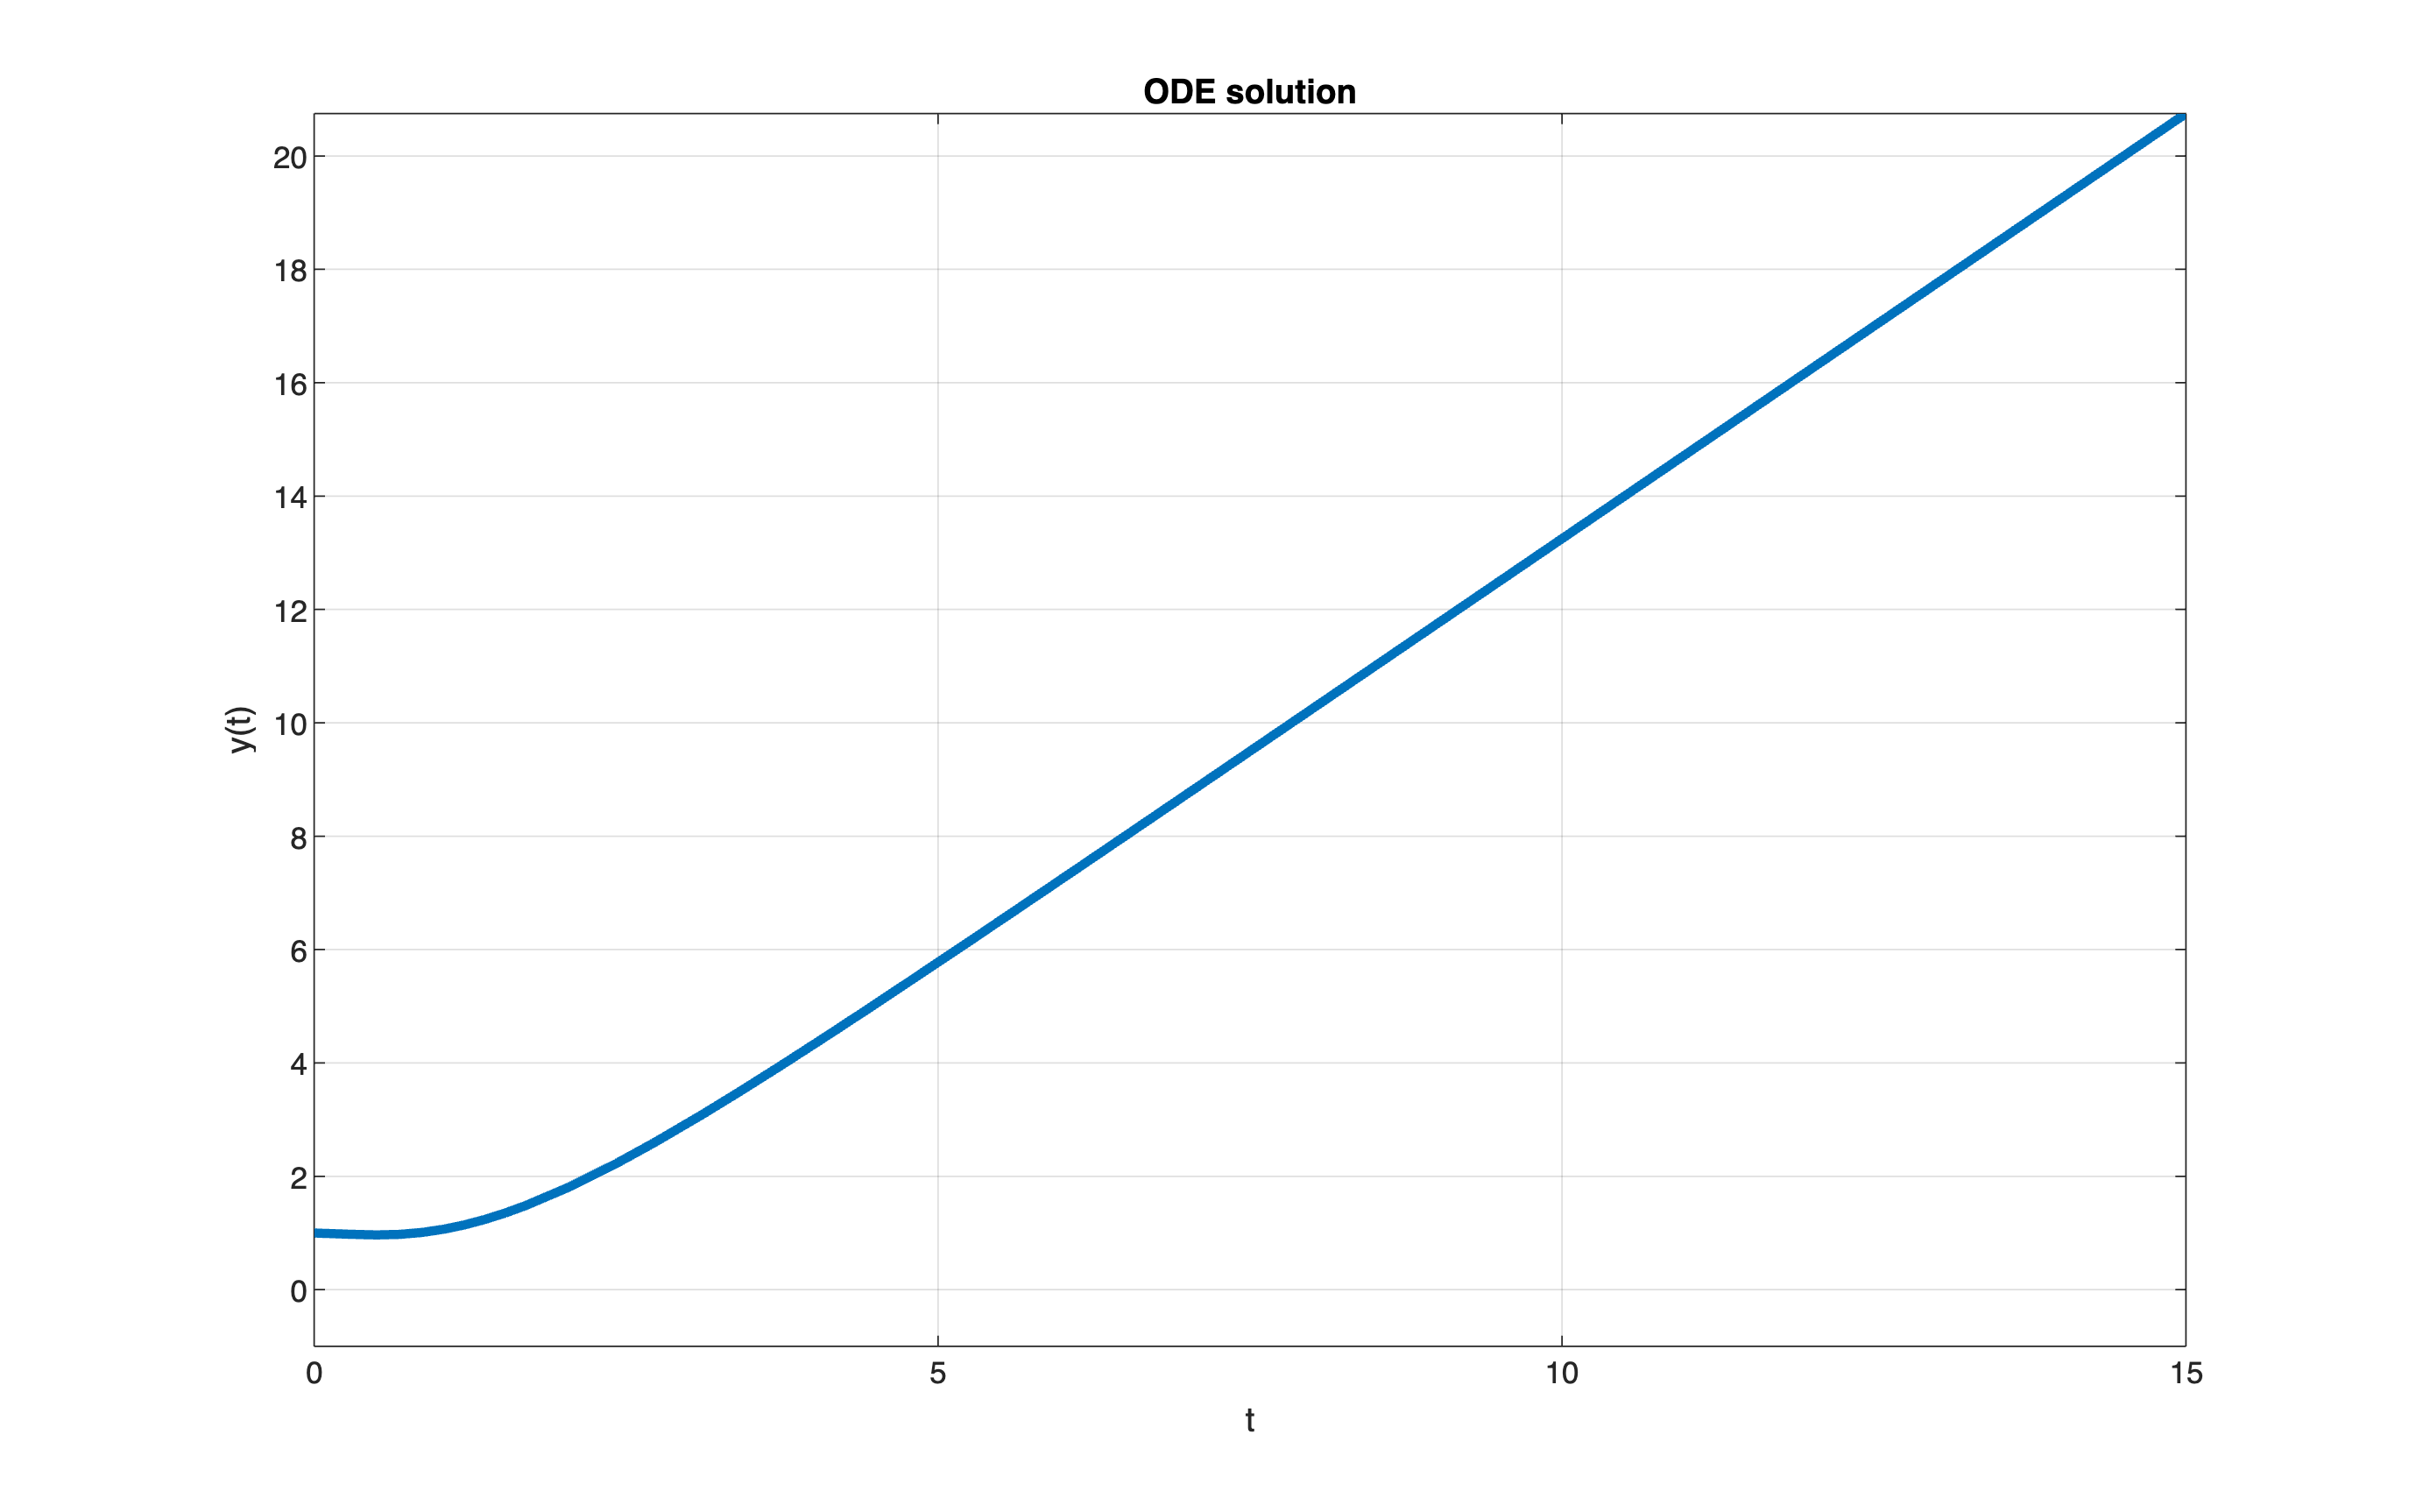

$$A = \left(\begin{array}{cc} 0 & 1\\ 0 & -a \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ K \end{array}\right)$$

$$sIA\_inv = \left(\begin{array}{cc} \frac{1}{s} & \frac{1}{s\,\left(a+s\right)}\\ 0 & \frac{1}{a+s} \end{array}\right)$$

$$Us = \frac{2\,\left(\frac{\sqrt{3}\,s}{2}+2\right)}{s^{2}+16}$$

$$Xs = \left(\begin{array}{c} \frac{1}{s}+\frac{2\,K\,\left(\frac{\sqrt{3}\,s}{2}+2\right)}{s\,\left(s^{2}+16\right)\,\left(a+s\right)}\\ \frac{2\,K\,\left(\frac{\sqrt{3}\,s}{2}+2\right)}{\left(s^{2}+16\right)\,\left(a+s\right)} \end{array}\right)$$

$$xt = \begin{array}{l} \left(\begin{array}{c} \frac{K+4\,a}{4\,a}-\frac{4\,K\,\sin\left(4\,t\right)+4\,\sqrt{3}\,K\,\cos\left(4\,t\right)+K\,a\,\cos\left(4\,t\right)-\sqrt{3}\,K\,a\,\sin\left(4\,t\right)}{4\,a^{2}+64}-\frac{\sigma_{1}}{a\,\left(a^{2}+16\right)}\\ \frac{4\,\sqrt{3}\,K\,\sin\left(4\,t\right)-4\,K\,\cos\left(4\,t\right)+K\,a\,\sin\left(4\,t\right)+\sqrt{3}\,K\,a\,\cos\left(4\,t\right)}{a^{2}+16}+\frac{\sigma_{1}}{a^{2}+16} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-a\,t}\,\left(4\,K-\sqrt{3}\,K\,a\right) \end{array}$$

xt = ilaplace(Xs)